# Analyze Earthquakes

Explore earthquake data from the USGS web API: [http://earthquake.usgs.gov/earthquakes/search/](http://earthquake.usgs.gov/earthquakes/search/)

## Read earthquake data

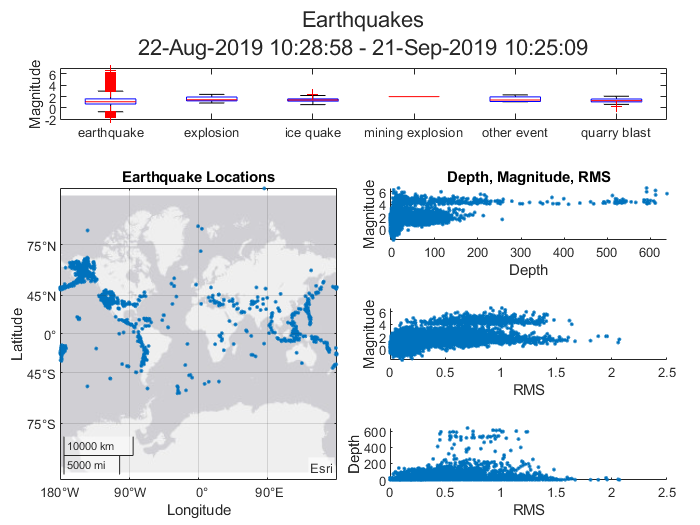

recentQuakeData = true;
quakes0 = ReadQuakes(recentQuakeData);

 

plotEarthquakeData(quakes0)
[tmin,tmax] = bounds(quakes0.time);
sgtitle(["Earthquakes",...
    string(tmin)+" - "+string(tmax)])

## Visualize earthquakes

Experiment with magnitude values and select plots to create. 

magvalue =1;
visualizeDensity = true;
visualizeByType = true;

Select data by magnitude and plot earthquakes.

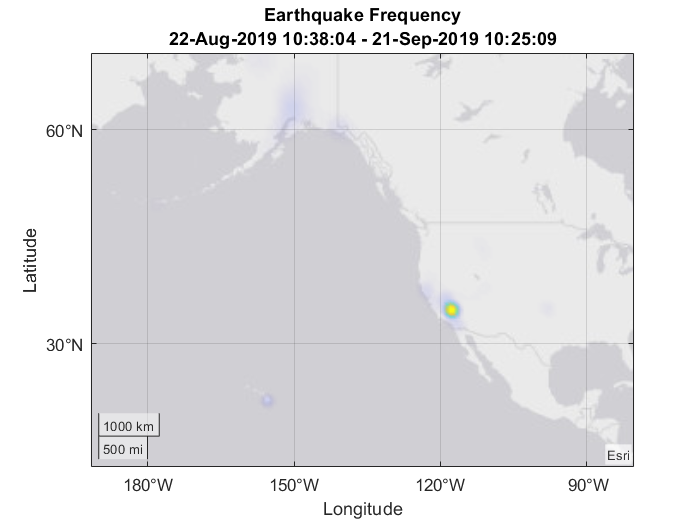

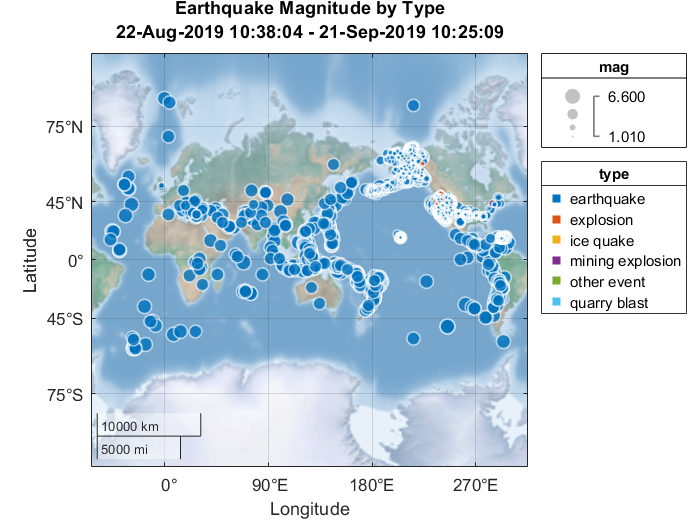

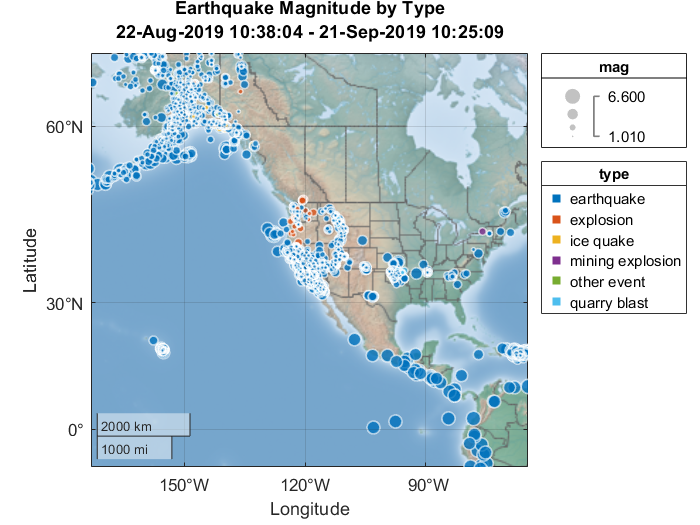

quakes = quakes0(quakes0.mag > magvalue,:);
quakes.type = removecats(quakes.type);
[tmin,tmax] = bounds(quakes.time);

if visualizeDensity
    figure
    geodensityplot(quakes.latitude,quakes.longitude,"FaceColor","interp");
    title(["Earthquake Frequency",...
        string(tmin)+" - "+string(tmax)])
    geolimits([6.1 67.0],[-189.9 -82.0])
end

if visualizeByType
    figure
    geobubble(quakes,"latitude","longitude","SizeVariable","mag",...
        "ColorVariable","type","Basemap","colorterrain",...
        "BubbleWidthRange",[2 10]);
    title(["Earthquake Magnitude by Type",...
        string(tmin)+" - "+string(tmax)])

    typeQuakes = groupsummary(quakes,"type","max","mag");
    maxTypes = max(typeQuakes.max_mag(typeQuakes.type ~= "earthquake"));
    if length(typeQuakes.type) > 1 && magvalue <= maxTypes
        figure
        geobubble(quakes,"latitude","longitude","SizeVariable","mag",...
            "ColorVariable","type","Basemap","colorterrain",...
            "BubbleWidthRange",[2 10]);
        title(["Earthquake Magnitude by Type",...
            string(tmin)+" - "+string(tmax)])                
        geolimits([-9.3 67.9],[-173.2 -64.6])
    end
end

Visualize earthquake frequency with a wordcloud.

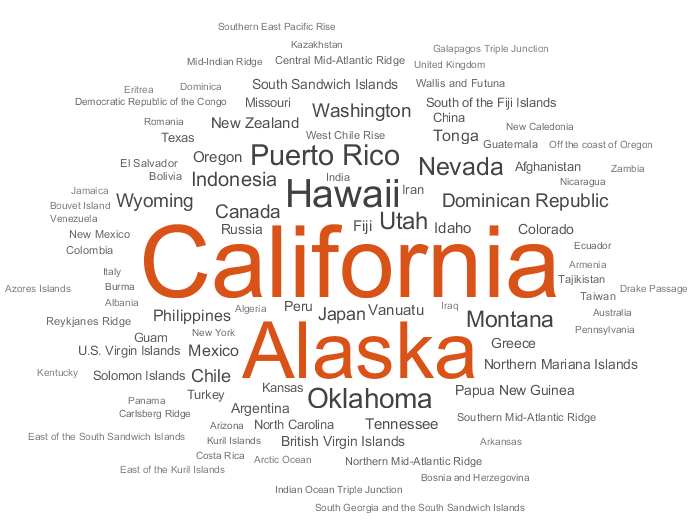

wordcloud(quakes.Loc);

Display locations with the most frequent and highest magnitudes.

mnByLoc = groupsummary(quakes,"Loc","mean","mag");
topLoc = topkrows(mnByLoc,50,"GroupCount");
topFrequency = topLoc(1:10,:)

topFrequency = 10×3 table
        Loc        GroupCount    mean_mag
    ___________    __________    ________

    California        4131        1.4772 
    Alaska            2438        1.7376 
    Hawaii             461         1.922 
    Puerto Rico        200        2.2142 
    Oklahoma           183        1.7832 
    Nevada             137        1.5453 
    Utah               125        1.6644 
    Montana             99         1.507 
    Indonesia           75        4.5907 
    Canada              55        1.7615 


topMagnitudes = topkrows(mnByLoc,10,"mean_mag")

topMagnitudes = 10×3 table
                Loc                GroupCount    mean_mag
    ___________________________    __________    ________

    Southern East Pacific Rise          2            5.6 
    Southeast of Easter Island          1            5.5 
    Azores Islands                      1            5.4 
    Bouvet Island                       1            5.4 
    Tanzania                            1            5.4 
    South China Sea                     1            5.3 
    North of Svalbard                   1            5.2 
    Northern Mid-Atlantic Ridge         7         5.1571 
    South Sandwich Islands             13         5.1385 
    Drake Passage                       1            5.1 


**Helper functions**

function plotEarthquakeData(quakes)
warning("off","MATLAB:handle_graphics:Layout:NoPositionSetInTiledChartLayout")

tiledlayout(4,2,"TileSpacing","compact","Padding","compact");
nexttile([1 2])
boxplot(quakes.mag,quakes.type)
ylabel("Magnitude")
nexttile(3,[3 1])
geoscatter(quakes.latitude,quakes.longitude,"Marker",".")
title("Earthquake Locations")
nexttile
scatter(quakes.depth,quakes.mag,".");
xlabel("Depth"); ylabel("Magnitude")
title("Depth, Magnitude, RMS")
nexttile
scatter(quakes.rms,quakes.mag,".");
xlabel("RMS"); ylabel("Magnitude")
nexttile
scatter(quakes.rms,quakes.depth,".");
xlabel("RMS"); ylabel("Depth")
warning("on","MATLAB:handle_graphics:Layout:NoPositionSetInTiledChartLayout")
end